mojave = robot

Updating server code on board Nano33BLE (COM28). This may take a few minutes.


mojave =   robot with properties:

        arduino: [1×1 arduino]
          lidar: [1×1 serial]
    steer_servo: []
         ir_vec: ["A1"    "A2"    "A3"    "A6"]
      sonar_vec: ["A0"    "A7"]
        lsm_obj: []
            neo: []


%mojave.lidar_setup();
% mojave.setup(); % can't run yet because not plugged into arduino 
% mojave.lidar_setup(); % can't run yet because not plugged into lidar 

% Camera test
% mojave.setup_USB_camera();
% img = mojave.sense_cam();
% mojave.robot_cam
% imshow(img)
mojave.lidar_setup();

% LiDAR initialize figure test
mojave.initialize_lidar_display();
%fopen(mojave.lidar)
% set(mojave.lidar, "Timeout", 3);
% set(mojave.lidar, "InputBufferSize", 20000);
% set(mojave.lidar, "Terminator", "LF");

LaserPlot1 = struct with fields:
    figure: [1×1 Figure]


Laser scan figure set
    "Target found between angles "    "96.7742"    " & "    "114.0176"

There is an obstacle 1059.6835 mm long 15mm away.
    "Target found between angles "    "96.7742"    " & "    "114.0176"

There is an obstacle 1058.6835 mm long 15mm away.
    "Target found between angles "    "96.7742"    " & "    "114.0176"

There is an obstacle 1069.6834 mm long 15mm away.
    "Target found between angles "    "96.7742"    " & "    "111.2023"

There is an obstacle 1115.4793 mm long 15mm away.
    "Target found between angles "    "96.7742"    " & "    "114.0176"

There is an obstacle 1054.6836 mm long 15mm away.
    "Target found between angles "    "96.7742"    " & "    "114.0176"

There is an obstacle 1049.6836 mm long 15mm away.
    "Target found between angles "    "96.7742"    " & "    "114.0176"

There is an obstacle 1053.6836 mm long 15mm away.
    "Target found between angles "    "96.7742"    " & "    "114.0176"

There is an obstacle 1045.6836 mm long 15mm away.
  

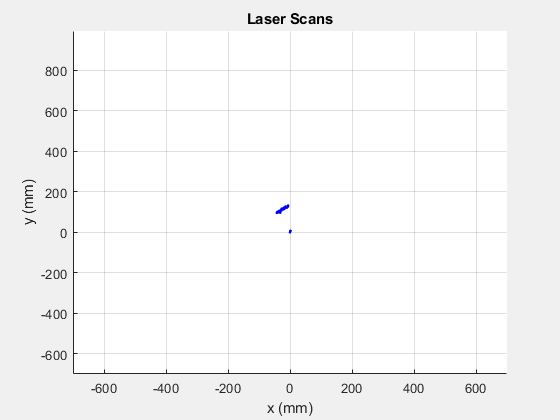

    "Target found between angles "    "92.5513"    " & "    "114.0176"

There is an obstacle 51.4961 mm long 132mm away.


Array indices must be positive integers or logical values.

Error in robot/lidar_scan (line 112)
                    if distance_to_object(ang_step) < distance_threshold && distance_to_object(ang_step) > 10

mojave.lidar_scan();

mojave.setup();

Setup complete


range_data_ir = mojave.ir_scan()

range_data_ir =          0         0         0    3.0993


range_data_sonar = mojave.sonar_scan()

range_data_sonar =     3.0800    3.3000


fclose(mojave.lidar);

mojave.steer(0.5);

Check for incorrect argument data type or missing argument in call to function 'writePosition'.

Error in robot/steer (line 298)
            writePosition(obj.steer_servo,pos);

clear mojave